# Método de Regresión Lineal por Mínimos Cuadrados

## Armando Terrazas Gómez | A01640924

## Liliana Solórzano Pérez | A01641392

## Fernando Gómez Martínez | A01641228

## Diego Partida Romero  |  A01641113

      
$$a=\frac{n\sum xy-\sum x\sum y}{n\sum x^2 -{\left(\sum x\right)}^2 }$$


          
$$b=\frac{\sum y-a\sum x}{n}$$



$$r=\frac{\sum \left(x-x^- \right)\left(y-y^- \right)}{√\sum {\left(x-x^- \right)}^2 √\sum {\left(x-x^- \right)}^2 }$$


df = 6×2 table
    Años    Población
    ____    _________

    2012        10   
    2013      10.9   
    2014      11.7   
    2015      12.6   
    2016      13.8   
    2017      14.9   


r = 0.9971

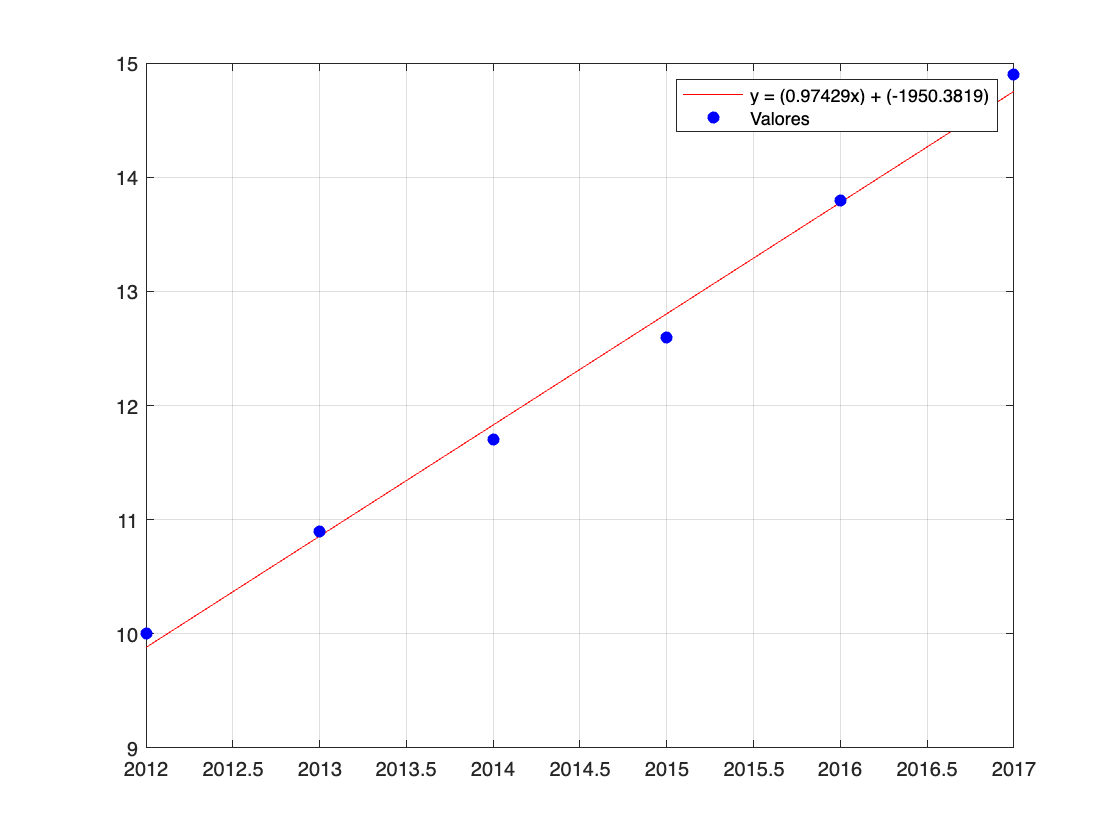

years = 2012:2017;
popul = [10 10.9 11.7 12.6 13.8 14.9];
varnamesYears = ["Años","Población"];
 
eq = LinealRegression(years,popul,varnamesYears);

x = 2018;
while (eq(x) < popul(3)*2)
    x = x+1;
end
fprintf("En el año %d habrá el doble del población a la del 2014:\n%.4f \n",x,eq(x))

En el año 2026 habrá el doble del población a la del 2014:
23.5210 


df = 9×2 table
    T(ºC)    S(g NaCl/100 g H2O)
    _____    ___________________

     10                35       
     20              35.6       
     30             36.25       
     40              36.9       
     50              37.7       
     60              38.1       
     70              38.8       
     80              39.4       
     90                40       


r = 0.9992

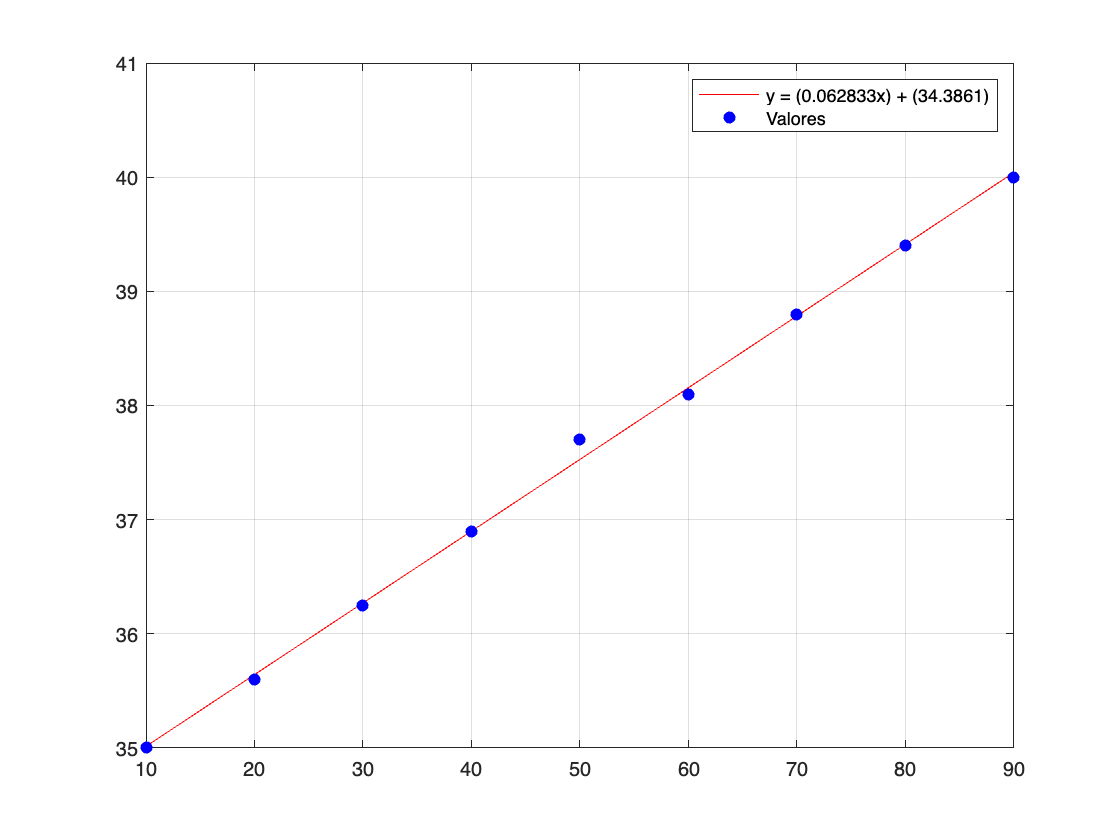

grados = 10:10:90;
sal = [35 35.6 36.25 36.9 37.7 38.1 38.8 39.4 40];
varnamesSal = ["T(ºC)","S(g NaCl/100 g H2O)"];
eq2 = LinealRegression(grados,sal,varnamesSal);

fprintf("La predicción de la solubilidad de la sal a 25º:\n%.4f",eq2(25))

La predicción de la solubilidad de la sal a 25º:
35.9569

function f = LinealRegression(X,y,varnames)
    
    df = table(X',y');
    df.Properties.VariableNames = varnames
    
    n = length(X);
    X2 = X.^2;
    xy = X.*y;

    a = ( n.*sum(xy) - sum(X).*sum(y) )/( n.*sum(X2) - sum(X).^2 );
    b = ( sum(y) - a.*sum(X) )/(n);

    f = @(x) a.*x + b;

    x_xmean = X-mean(X);
    y_ymean = y-mean(y);
    x_xmean_y_ymean = x_xmean.*y_ymean;
    
    r = (sum(x_xmean_y_ymean))/( sqrt(sum(x_xmean.^2)) .* sqrt(sum(y_ymean.^2)) );

    yfit = f(X);
    
    plot(X,yfit,'r')
    hold on
    scatter(X,y,'filled','b')
    
    grid on;
    equation = "y = (" + string(a) + "x) + (" + string(b) + ")";
    legend(equation,"Valores")
    fprintf("r = %.4f",r)
    hold off
end
